## 1 + 2: Input runData and modelData

tic
%clear runData modelData;
% Settings to run model
runData.filename = 'testgif.gif';   % put in name of gif
runData.runType = 'time';
runData.checkGeometry = true;
runData.plotSolution = true;
runData.hmax = 0.05;                % mesh size: default hmax = 0.05
runData.dataset = 'Temp_driven';  
%runData.group = 1;                  
runData.nEquations = 1;
runData.YZslice = "zero";           % set "two" to activate

% Load material properties and sources
[modelData.Heat,modelData.Heat_info] = h4_heatProperties_EK(runData.dataset);
% Material assignment to model domains
modelData.materialIDs = [1,2,2];    % define differently if different material per face (# faces = 3, so 3 elements)

% Source assignment to model domains
modelData.sourceIDs = [1,2,2];      % define differently if different source term (more heat /concentration)
modelData.seedheat = 1*10*1.066*60; % --> SAR_NP * rho * mass% * s/min

## Create model, geometry and mesh

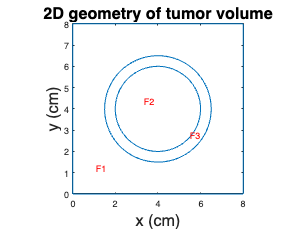

% Create PDE model
[model,modelData] = s1_createPDEModel(runData,modelData);
% Load test geometry
[model,~,centretumor,diametertumor] = t2_createGeometry2D(model,runData);

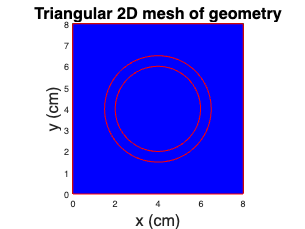

% Generate mesh
[model] = s3_createMesh2D(model,runData);

toc

Elapsed time is 6.069475 seconds.


## 4: Set BC, IC and time scale

tic
% Boundary conditions:      only applicable for outer boundaries
runData.nBCs.neumann = 1;                                   % necessary to define if multiple neumann boundaries with different values
runData.BCs.neumann(1) = struct('edge',1:4,'q',0,'g',0);    % flux breast [#NPs/m2*s] % must depend on current temperature to not become negative.
%runData.BCs.neumann(2) = struct('edge',[2 3],'q',0,'g',0); % flux tumor [#NPs/m2*s]
runData.nBCs.dirichlet = 1;
runData.BCs.dirichlet(1) = struct('edge',[],'u',(273.15+37));     % [] means isempty

% Initial conditions
[modelData.x0, modelData.y0, noSeeds] = t4_3_XZ_seedlocationssquare(diametertumor,centretumor);
runData.nICs = 1;                                           % necessary to define if multiple initial conditions different per face
modelData.Tinit = 310.15;                                   % 'constant' temperature breast tissue
runData.IC(1) = struct('u',modelData.Tinit,'Face',1:3);     % initial temperature in body and tumour

% Time scale
m = 60; % number of minutes % default total time  = 60 min
runData.timePoints = 0:0.1:m;  % timestep

% Load BC and IC
[model] = s4_2_loadBCIC(model,modelData,runData);
toc

Elapsed time is 0.765648 seconds.


## 3 + 5: Solve system of PDE 

time = datestr(now, 'HH:MM')

time = '10:03'

tic
% Solve PDE model
[~,results] = h5_XZ_NPHeat2D(model,modelData,runData);
toc

Elapsed time is 211.251474 seconds.


%u = results.NodalSolution; 
%s6_plotPDESolution(model,u,runData)
modelData.Tresults = results.NodalSolution - 273.15;
Tresults = results.NodalSolution - 273.15;

## 6: Results: av/min/max temperature

% Calculate maximum, minimum and average results over time
tic
modelData.solMin = min(modelData.Tresults);
modelData.solMax = max(modelData.Tresults);
r = [2 , 2.5 , 3.5];    % Radius of tumour volume taken into account                        % Radius of tumour volume taken into account
[modelData] = h6_2_Tresults_average(model,modelData,r(1),r(2),r(3),centretumor(1)); % T values (max,min,average) in GTV

maxT_GTV = 97.4159

averageT_GTV = 67.2283

minT_GTV = 51.2255

maxT_PTV = 54.9392

averageT_PTV = 48.8512

minT_PTV = 45.3195

maxT_1cm = 46.8665

averageT_1cm = 41.3373

minT_1cm = 38.7642

[averageT,minT,results] = h6_2_Tresults_time(model,modelData,r(1),centretumor(1));  % averageT and minT only in tumour area

minT =    37.0000
   37.0000
   37.0000
   37.0001
   37.0004
   37.0018
   37.0050
   37.0116
   37.0231
   37.0384


averageT =    37.0000
   37.3474
   37.6982
   38.0505
   38.4024
   38.7525
   39.0998
   39.4437
   39.7836
   40.1199


solMax = modelData.solMax;                                                          % maxT in total area

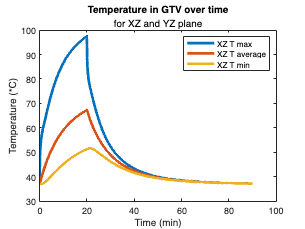

% plot
runData.timePointsX = 0:0.1:60;
figure
plot(runData.timePoints,solMax,'LineWidth',3)
hold on
plot(runData.timePoints,averageT,'LineWidth',3)
plot(runData.timePoints,minT,'LineWidth',3)
title('Temperature in GTV over time')
txt = {'for XZ and YZ plane'};
subtitle(txt)
ylabel("Temperature (*C)")
xlabel("Time (min)") 
legend("XZ T max","XZ T average","XZ T min")%,"YZ T max","YZ T average","YZ T min")

## Save results

save Tresults_wb_constant Tresults solMax averageT minT Xnodes Ynodes

## 6: Calculated added heat: Tmax, Tav, Tmin

maxheat = [model.Mesh.Nodes' modelData.Tresults];
[modelData.solMax,I] = max(maxheat(:,201));
modelData.solMax = maxheat(I,3:end);
solMax2 = max(max(modelData.Tresults))

solMax = 97.4159

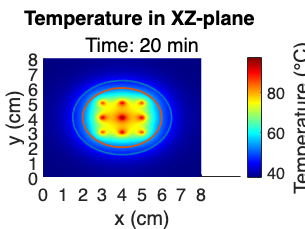

[model] = h6_results2D(model,modelData,runData);

## 6: Spread of heat: Intersection

[model] = h6_results2D(model,modelData,runData);


spread1 = Tresults_XZ_default.Tresults(:,201);

Unable to resolve the name 'Tresults_XZ_default.Tresults'.

spread2 = Tresults_XZ_default.Tresults(:,203);
spread3 = Tresults_XZ_default.Tresults(:,206);
spread4 = Tresults_XZ_default.Tresults(:,211);

Xnodes = Tresults_XZ_default.Xnodes;
Ynodes = Tresults_XZ_default.Ynodes;
Xnodes2 = Tresults_XZ_default.Xnodes;
Ynodes2 = Tresults_XZ_default.Ynodes;

Xnodes3 = Tresults_XZ_default.Xnodes;
Ynodes3 = Tresults_XZ_default.Ynodes;
Xnodes4 = Tresults_XZ_default.Xnodes;
Ynodes4 = Tresults_XZ_default.Ynodes;

heatspread1 = [Xnodes Ynodes spread1];
heatspread2 = [Xnodes2 Ynodes2 spread2];
heatspread3 = [Xnodes3 Ynodes3 spread3];
heatspread4 = [Xnodes4 Ynodes4 spread4];

for i = 1:length(heatspread1(:,2))
    if heatspread1(i,2) >= 4.01 || heatspread1(i,2) <= 3.98
        heatspread1(i,2) = 0;
    end
end
heatspread1(any(heatspread1(:,2)==0,2),:) = [];
heatspread1 = sortrows(heatspread1,1);

for i = 1:length(heatspread2(:,2))
    if heatspread2(i,2) >= 4.01 || heatspread2(i,2) <= 3.98
        heatspread2(i,2) = 0;
    end
end
heatspread2(any(heatspread2(:,2)==0,2),:) = [];
heatspread2 = sortrows(heatspread2,1);

for i = 1:length(heatspread3(:,2))
    if heatspread3(i,2) >= 4.01 || heatspread3(i,2) <= 3.98
        heatspread3(i,2) = 0;
    end
end
heatspread3(any(heatspread3(:,2)==0,2),:) = [];
heatspread3 = sortrows(heatspread3,1);

for i = 1:length(heatspread4(:,2))
    if heatspread4(i,2) >= 4.01 || heatspread4(i,2) <= 3.98
        heatspread4(i,2) = 0;
    end
end
heatspread4(any(heatspread4(:,2)==0,2),:) = [];
heatspread4 = sortrows(heatspread4,1);

figure
plot(heatspread1(:,1),heatspread1(:,3),'-','Linewidth',1.5)
hold on
plot(heatspread2(:,1),heatspread2(:,3),'-','Linewidth',1.5)
plot(heatspread3(:,1),heatspread3(:,3),'-','Linewidth',1.5)
plot(heatspread4(:,1),heatspread4(:,3),'-','Linewidth',1.5)
xline(2)
xline(1.5)
xline(6)
xline(6.5)
title('Spread of heat at different points in time')
txt = {'intersection through centre'};
subtitle(txt)
ylabel("Temperature (*C)")
xlabel("Distance (cm)")
legend('t = 20 min','t = 20.25 min','t = 20.5 min','t = 21 min');

## 6: Spread of heat: Over time

figure
plot(runData.timePoints,Tresults_default.solMax,'LineWidth',3)
hold on
plot(runData.timePoints,Tresults_t_min.solMax,'LineWidth',3)
plot(runData.timePoints,Tresults_t_max.solMax,'LineWidth',3)
title('Maximum temperature in GTV over time')
txt = {'for different AMF times'};
subtitle(txt)
ylabel("Temperature (*C)")
xlabel("Time (min)") 
legend('t = 20 min','t = 20.25 min','t = 20.5 min','t = 21 min');

figure
plot(runData.timePoints,Tresults_default.minT,'LineWidth',3)
hold on
plot(runData.timePoints,Tresults_t_min.minT,'LineWidth',3)
plot(runData.timePoints,Tresults_t_max.minT,'LineWidth',3)
title('Minimum temperature in GTV over time')
txt = {'for different AMF times'};
subtitle(txt)
ylabel("Temperature (*C)")
xlabel("Time (min)") 
legend('t_{switch} = 20 min','t_{switch} = 18 min','t_{switch} = 22 min');

figure
plot(runData.timePoints,Tresults_default.averageT,'LineWidth',3)
hold on
plot(runData.timePoints,Tresults_t_min.averageT,'LineWidth',3)
plot(runData.timePoints,Tresults_t_max.averageT,'LineWidth',3)
title('Average temperature in GTV over time')
txt = {'for different AMF times'};
subtitle(txt)
ylabel("Temperature (*C)")
xlabel("Time (min)") 
legend('t_{switch} = 20 min','t_{switch} = 18 min','t_{switch} = 22 min');%,"YZ T max","YZ T average","YZ T min")
